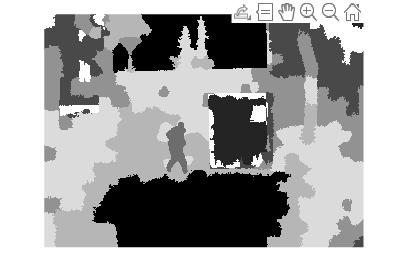

% 读取图像
image = imread('1.bmp');

% 将图像转换为一个矩阵
matrix = double(reshape(image, size(image, 1) * size(image, 2), size(image, 3)));

% 设置聚类的数量
k = 8;

% 使用K均值算法进行聚类
[idx, ~] = kmeans(matrix, k);

% 将每个像素的索引转换为彩色图像
segmented_image = reshape(idx, size(image, 1), size(image, 2));

% 显示聚类结果
imshow(segmented_image, []);